# Mitochondrial maps

These maps are from Mosharov et al. 2025, Nature, uploaded to Neurovault. The study sampled 700 voxels from one slice of one hemisphere of a post-mortem participant, and used group-average HCP data (T1, DWI, etc.) to predict the mitochondrial density (MitoD), mitochondrial respiratory capacity (MRC), and tissue respiratory capacity (TRC) in some voxels from MRI measures in other voxels. Then, they extrapolated the predicted values to the rest of the brain (i.e., estimated fitted values for MitoD, TRC, and MRC).  The resulting maps are what is stored and visualized here.

The predictive model training appears to have been done on held-out voxels, violating the independence of errors across training and test datasets and thus resulting in overfitting. The inclusion of the maps here is not an endorsement of the method. However, the resulting maps may be useful estimates of patterns of variation in mitochondria-related measures across the brain. They should be interpreted as maps of predicted, not actual, mitochondrial measures. 

CI, CII, and CIV relate to mitochondrial complexes 1, 2, and 4.

If you use the data from this collection please cite Mosharov et al. 2025 and include the following persistent identifier in the text of your manuscript:

`https://identifiers.org/neurovault.collection:16418`

% cd('/Users/f003vz1/Documents/GitHub/Neuroimaging_Pattern_Masks/spatial_basis_functions/mitochondrial_profile_maps')

obj = fmri_data(filenames(fullfile(pwd, '*.nii.gz')));

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 46657704 bytes
Loading image number:     6
Elapsed time is 0.163622 seconds.
Re-zipping image files.
Number of unique values in dataset: 4598071  Bit rate: 22.13 bits


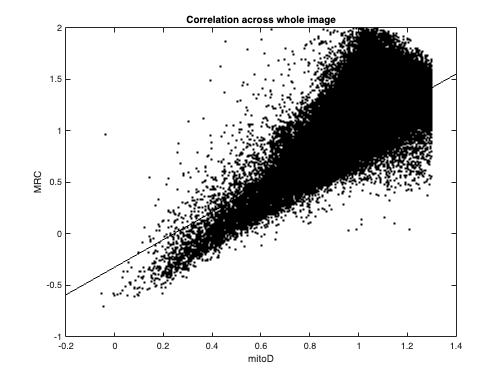


% names = strrep(cellstr(obj.image_names), '.nii', '')'


% d is data with complete cases only; eliminate 0 (empty) values
d = obj.dat;
d(any(abs(d) < 1000 * eps, 2), :) = [];
figure; plot(d(:, 4), d(:, 5), 'k.'); refline
xlabel('mitoD'), ylabel('MRC')
title('Correlation across whole image')

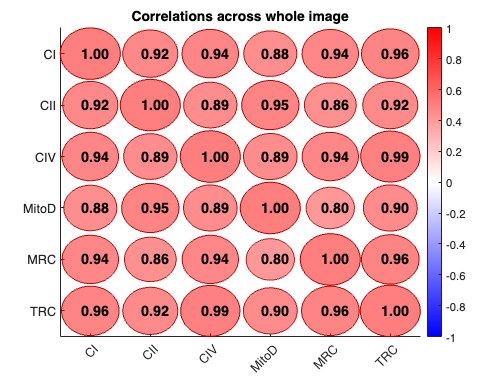


plot_correlation_matrix(d, 'names', names);
title('Correlations across whole image')

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 15122 voxels displayed, 1619104 not displayed on these slices
sagittal montage: 14794 voxels displayed, 1619432 not displayed on these slices
sagittal montage: 7652 voxels displayed, 1626574 not displayed on these slices
axial montage: 118896 voxels displayed, 1515330 not displayed on these slices
axial montage: 125666 voxels displayed, 1508560 not displayed on these slices


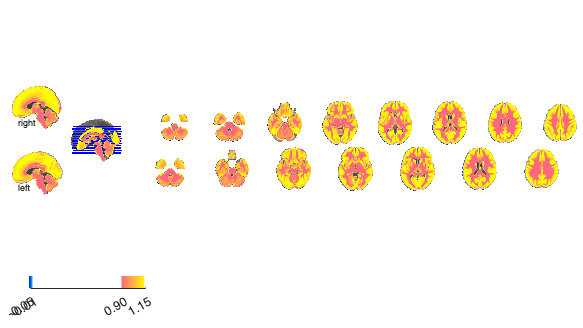

% Look at example images

mitoD = get_wh_image(obj, 4);
figure; montage(mitoD);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 16031 voxels displayed, 1692742 not displayed on these slices
sagittal montage: 15760 voxels displayed, 1693013 not displayed on these slices
sagittal montage: 14348 voxels displayed, 1694425 not displayed on these slices
axial montage: 123564 voxels displayed, 1585209 not displayed on these slices
axial montage: 132400 voxels displayed, 1576373 not displayed on these slices


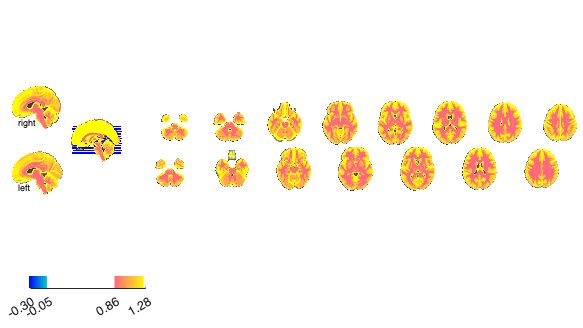


MRC = get_wh_image(obj, 5);
figure; montage(MRC);

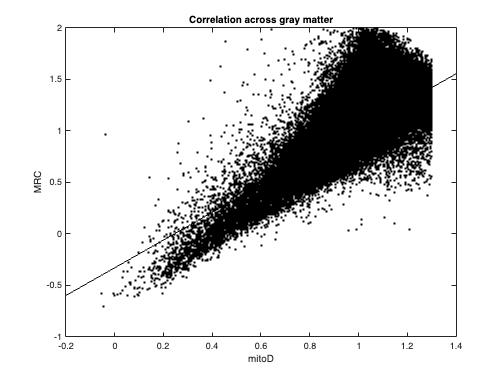

% Apply gray-matter mask and examine correlations again

obj_masked = apply_mask(obj, which('gray_matter_mask.nii'));

% d is data with complete cases only; eliminate 0 (empty) values
d = obj_masked.dat;
d(any(abs(d) < 1000 * eps, 2), :) = [];
figure; plot(d(:, 4), d(:, 5), 'k.'); refline
xlabel('mitoD'), ylabel('MRC')
title('Correlation across gray matter')

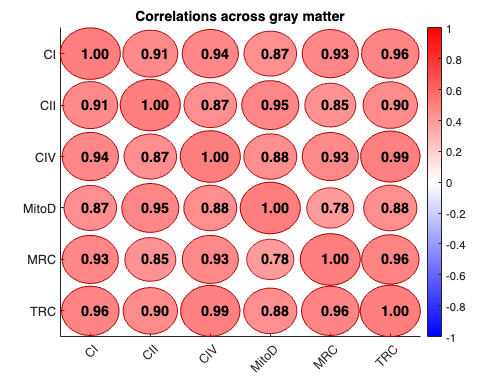


plot_correlation_matrix(d, 'names', names);
title('Correlations across gray matter')

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 15004 voxels displayed, 1496476 not displayed on these slices
sagittal montage: 14651 voxels displayed, 1496829 not displayed on these slices
sagittal montage: 7345 voxels displayed, 1504135 not displayed on these slices
axial montage: 108785 voxels displayed, 1402695 not displayed on these slices
axial montage: 115228 voxels displayed, 1396252 not displayed on these slices


% Look at example images if we don't zero out missing values (complete cases)
% The correlations change dramatically

mitoD = get_wh_image(obj_masked, 4);
figure; montage(mitoD);

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 15867 voxels displayed, 1567649 not displayed on these slices
sagittal montage: 15573 voxels displayed, 1567943 not displayed on these slices
sagittal montage: 13813 voxels displayed, 1569703 not displayed on these slices
axial montage: 113297 voxels displayed, 1470219 not displayed on these slices
axial montage: 121664 voxels displayed, 1461852 not displayed on these slices



MRC = get_wh_image(obj_masked, 5);
figure; montage(MRC);

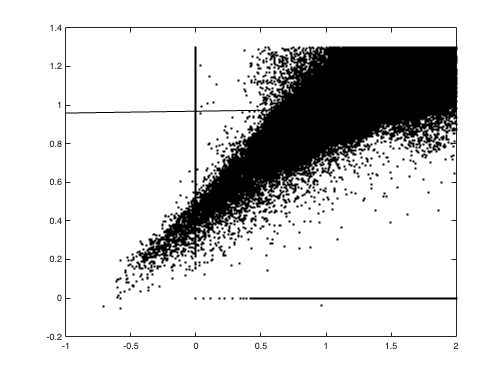


figure; plot(MRC.dat, mitoD.dat, 'k.'); refline

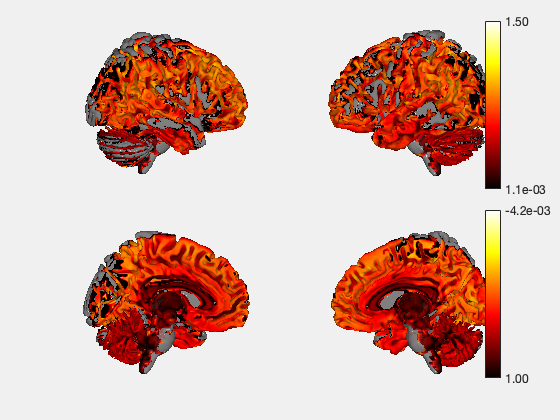

% Surface figure in cortex specifically, thresholded

mitoD = get_wh_image(obj, 4);

figure; surface(mitoD, 'foursurfaces', 'cmaprange', [1 1.5]);

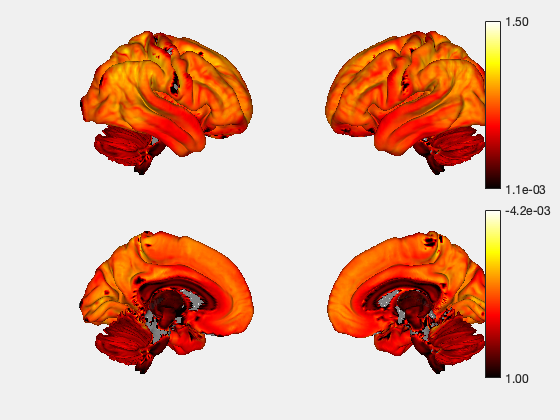

drawnow; snapnow

% this looks better...not positive that MNI152NLin6Asym is the right space
% (check the paper/investigate if you use this in publication)
figure; surface(mitoD, 'foursurfaces_hcp', 'cmaprange', [1 1.5], 'sourcespace', 'MNI152NLin6Asym', 'targetspace', 'fsaverage_164k');

save mito_maps obj obj_masked names

